# Finalization of the video encoder

## Inter image coding

In the previous labs, we have implemented the INTRA and INTER coding for a single block, as well as the INTRA coding for a whole image. Now the focus is on Inter coding of the whole image. We start by listing the features that should be supported by the function performing the INTER coding; then a partial implementation of the function is provided. **The first goal of this lab is **to understand and complete it. Finally, the new function is integrated into the full video codec. **The second goal** is to use the complete video encoder to perform some experiments: a list of possibilities is provided. **In the final report you should provide the results of the experiments and, most importantly, your comments. **

## Features of the Inter Image coding function

#### Image pre-processing

Contrary to what we did for INTRA images, in the proposed implementation we do not subtract 128 to the image before starting the encoding process. This choice simplifies somewhat the encoding process. 

#### Rate-distortion omptimized mode selection (RDO-MS)

An important feature of this function is that it should implement the **rate-distortion optimized mode selection (RDO-MS)**. What does it means? It means that each block must *first* be encoded in both INTRA and INTER mode; *then*, the encoding function evaluate the RD cost $J=D+\lambda \;R$ and choose the mode that minimizes the cost. The parameter $\lambda$ is stored in the `params` global variable. We notice that this parameter has a similar, but different role than $\lambda_{\textrm{ME}}$: $\lambda \;$allows to weights between the coding rate and the MSE of a block; $\lambda_{\textrm{ME}}$ allows to weight between the coding rate of a *motion vector* and the MSE of the predictor. However, in both cases, we should use a large value of the lagrangian parameter if the available bit rate is small. In practice, the values of the parameters are chosen empirically as a function of the quality factor. In our implementation, we set a fixed value of $\lambda \;$and set $\lambda {\;}_{\textrm{ME}} =\sqrt{\;\lambda \;}$ (which is common practice). 

#### Coding cost maps `map.JIntra` and `map.JInter`

In order to collect some statistics about the mode selection the `IntraIngEncoder` function will return the coding costs of all the blocks, both for Intra and Inter mode. In this way, we can have further insight about the relationship between the content and the mode decision. This information is stored in the output variable `map`, which in turn has two fields: `map.JIntra` and `map.JInter`. Each one is a matrix with one entry per image block. Thus, each map's number of rows or columns is obtained from the image number of rows or columns divided by the block size. The value of each entry is the coding cost computed with the respective mode. 

#### The Motion Vector Field `MVF`

Using RDO-MS implies that each block of the INTER image can be encoded either in INTRA or in INTER mode. However, in order to encode the motion vector of an INTER block, we need the motion vectors of its neighboring blocks. We store all the computed motion vectors in a global variable named `MVF`. 

How to cope with the case when one or more of the neighboring blocks are encoded in INTRA mode? they will not have an associated motion vector. A simple solution folows: both the encoder and the decoder agree that, when a block is encoded as INTRA, it has a "virtual" motion vector equal to (0,0). This virtual neighbor is used in the MV prediction process as it was a "real" one. In conclusion, we just need to be sure that, corresponding to INTRA-coded blocks, the motion vector field is null. 

Note that other, more efficient but more complicated solutions could be used (and actually are in modern video encoders), but the one proposed here is a reasonable compromise between complexity and efficiency. 

#### DC prediction

When we encode a blockof the INTER image as an INTRA block, we are not sure that the previous block has been encoded as INTRA as well. So the question is: how the perform DC prediction? Here we take a simple choice: we use the last DC coefficient from an INTRA block as predictor, and the predictor for the first INTRA block is set to 128 (remember that we did not remove 128 from the image in the preprocessing step). 

On the other hand, DC prediction makes less sense for INTER blocks, because the DCT is computed over a prediction residual. Therefore, we will call the `blockInterCoding` function with a conventionally zero value for the DC predictor, and we will not use the quantized DC coefficient produced by the DCT on the INTER block. 

#### Signalization

We notice that the INTER/INTRA decision must be signalled to the decoder; in other words, we must insert in the bitstream a bit that signals the decision about the mode that has been chosed to encode the block. 

#### The `InterImgEncoder` function

This function should encode the image stored in the global variable `img` and create the encoded bitstream as output parameter. In addition, it should use the global variable `decodedFrameBuffer.reference `as a reference for motion estimation and it should store the decoded current image in `decodedFrameBuffer.current. `Here we provide a version for `InterImgEncoder.m `that you have to complete, cut and past into a file, and finally test in the test enviroment provided later on. 

## Testing the Inter Image coding function

Once you complete the function, you can test it by using the following test environment. Here we encode an image using the Inter coding. The *reference* image used for temporal prediction is the Intra image of a GOP (you can specify the GOP size and the GOP number). For the sake of simplicity, we will use the *original* intra image as reference. You can choose the temporal distance between the reference and the image to be encoded via the `interIndex` parameter. 

You can also modify the values of $\lambda ,$ $\lambda_{\textrm{ME}}$ and of the search radius for motion estimation. As for the quality factor, it is defined as `params.qual-params.deltaQ`

If you keep all the parameters unchanged, you should obtain INTER RATE: 0.946 bpp and INTER PSNR: 39.72 dB.

The script also shows the maps of the coding costs for the INTRA and INTER mode, as well as the map of mode decisions. 

**Question 1. Complete the **`InterImageCoding.m`** function and perform some tests using the provided test environment. Use different video sequences (low motion vs. high motion) and comment about: the RD performance of INTRA coding wrt INTER; the coding cost achievable with the two modes and the relation with the video content (e.g., new objects appearing in the image, areas with low or high details, regular or complicated motion patterns, etc.)**

**param qual 90**

`INTER RATE: 0.943 bpp`

`INTER PSNR: 39.74 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

**param qual 75 **

`INTER RATE: 0.642 bpp`

`INTER PSNR: 38.28 dB`

`INTRA RATE: 0.781 bpp`

`INTRA PSNR: 40.00 dB`

`iNTRA vs INTER Performance:`

`params.qual Changes:`

`As the value of params.qual increases, the quality of the INTRA mode increases, and therefore the PSNR value, but also the bit rate increases. This provides better quality but more costly encoding.`

`As the params.qual value decreases, the quality and PSNR of the INTRA mode decreases, but the bit rate decreases. This results in lower quality but more economical encoding.`

`deltaQ 10`

`INTER RATE: 0.943 bpp`

`INTER PSNR: 39.74 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

`deltaQ 20`

`INTER RATE: 0.749 bpp`

`INTER PSNR: 38.06 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

INTRA mode maintains consistent quality and bit rate across different deltaQ values, indicating its stability and less sensitivity to deltaQ changes.

INTER mode benefits from higher deltaQ in terms of achieving lower bit rates, but at the cost of reduced PSNR (lower quality).

Increasing deltaQ improves the economic performance of INTER mode (lower bit rates) but sacrifices quality (lower PSNR).

DeltaQ has minimal impact on INTRA mode performance, as it generally operates at higher quality and bit rates.

GOPSIZE 5

`INTER RATE: 0.943 bpp`

`INTER PSNR: 39.74 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

GOPSIZE 2

`INTER RATE: 0.746 bpp`

`INTER PSNR: 39.90 dB`

`INTRA RATE: 1.815 bpp`

`INTRA PSNR: 41.18 dB`

Smaller GOP sizes (like GOP Size 2) lead to higher bit rates for both INTER and INTRA coding due to more frequent INTRA frames. This is evident from the higher bit rates observed in GOP Size 2 compared to GOP Size 5.

Larger GOP sizes (like GOP Size 5) generally result in lower bit rates but may sacrifice some quality (lower PSNR) due to less frequent updates in the reference frame.

`me.radius 10`

`INTER RATE: 0.928 bpp`

`INTER PSNR: 39.74 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

`me.radius 4`

`INTER RATE: 0.981 bpp`

`INTER PSNR: 39.84 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

When the radius (`me.radius`) is set to 10, the INTER mode achieves a lower bit rate (0.928 bpp), indicating improved coding efficiency with a larger motion estimation radius. However, the INTRA mode maintains a higher rate (1.269 bpp) with a higher PSNR (43.39 dB), demonstrating its superiority in preserving image quality.

Conversely, reducing the radius to 4 increases the INTER mode bit rate (0.981 bpp) while maintaining a similar PSNR (39.84 dB) to the radius 10 setting (39.74 dB). This suggests that a smaller motion estimation radius leads to slightly higher bit rates in INTER coding, though the perceptual quality remains largely unaffected.

These results highlight that the choice of motion estimation radius significantly influences the coding efficiency of the INTER mode, while its impact on perceived image quality, as indicated by PSNR, is minimal.

Inter index 3

`INTER RATE: 0.928 bpp`

`INTER PSNR: 39.74 dB`

`INTRA RATE: 1.269 bpp`

`INTRA PSNR: 43.39 dB`

`Inter index 6`

`INTER RATE: 0.927 bpp`

`INTER PSNR: 39.94 dB`

`INTRA RATE: 1.195 bpp`

`INTRA PSNR: 43.50 dB`

`INTER Mode Performance:`

`For both Inter Index 3 and 6, the INTER mode achieves similar bit rates (0.928 bpp vs. 0.927 bpp) and PSNR values (39.74 dB vs. 39.94 dB). This indicates that the temporal distance does not significantly affect the coding efficiency of the INTER mode in terms of bit rate and PSNR.`

`INTRA Mode Performance:`

`The INTRA mode shows a noticeable decrease in bit rate from 1.269 bpp (Inter Index 3) to 1.195 bpp (Inter Index 6), while maintaining consistently high PSNR values (43.39 dB vs. 43.50 dB). This suggests that increasing the temporal distance reduces the redundancy that the The INTER mode remains relatively stable in performance across these temporal distances, while the INTRA mode shows a more pronounced sensitivity to changes, particularly in terms of bit rate reduction with increased temporal distance.`

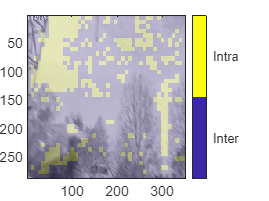

clear all; close all;
clc
global params img decodedFrameBuffer MVF

% Setting the configuration: you can change these paramters for testing:
params.inputVideoName = 'foreman'; % Use one of the provided .y files
params.verbose = 0;  % Setting the verboseness level might be useful for debugging and testing
params.qual = 90; % Quality factor for INTRA frame
params.deltaQ = 10; % difference of quality between INTRA and INTER
params.modeSelectionLambda = 10;
params.ME.lambda = sqrt(params.modeSelectionLambda);
params.ME.radius = 8;

params.GOPSize = 5;
gopIndex = 40;       % Choose the GOP index: we will use the first frame as a reference
interIndex = 3;      % this is the "temporal distance" between the reference (INTRA) and the frame to be encoded (INTER)
%------------------------------------

%------------------------------------
% Do not change these parameters: -->
params.inputVideoFile   = [params.inputVideoName '_cif.y'];   % full input file name. Add the path if needed
params.blockSize = 8;  %
params.nRow = 288;
params.nCol = 352;
decodedFrameBuffer.reference = zeros(params.nRow,params.nCol); % Since we do not use B, one decoded refernce is enough
decodedFrameBuffer.current   = zeros(params.nRow,params.nCol); % We also need a buffer for the current encoded image
MVF = zeros(params.nRow,params.nCol,2);
params.q_mtx1 =     [16 11 10 16 24 40 51 61;
    12 12 14 19 26 58 60 55;
    14 13 16 24 40 57 69 56;
    14 17 22 29 51 87 80 62;
    18 22 37 56 68 109 103 77;
    24 35 55 64 81 104 113 92;
    49 64 78 87 103 121 120 101;
    72 92 95 98 112 100 103 99];

% define the quantization matrix for Intra frames
SF_Intra = (params.qual==100)+(params.qual<=99&&params.qual>50)*(200-2*params.qual)+ (params.qual<=50)*(5000/params.qual);
params.q_mtx_Intra = ceil(params.q_mtx1*SF_Intra/100);
params.q_mtx_Intra (params.q_mtx_Intra >256)=256;

% define the quantization matrix for Inter frames
params.qual_Inter=max(min(params.qual - params.deltaQ,100),0);
SF_Inter = (params.qual_Inter==100)+(params.qual_Inter<=99&&params.qual_Inter>50)*(200-2*params.qual_Inter)+ (params.qual_Inter<=50)*(5000/params.qual_Inter);
params.q_mtx_Inter = ceil(params.q_mtx1*SF_Inter/100);
params.q_mtx_Inter (params.q_mtx_Inter >256)=256;
params.firstFrameGOP =  params.GOPSize*(gopIndex-1) + 1;
% <-- end of parameters that should not be changed
%------------------------------------


% Let us load two images from the selected GOP
% For the sake of simplicity, we put the original INTRA in the
% decodedFrameBuffer (in real life, here we would have the decoded INTRA
decodedFrameBuffer.reference= loadIntra(gopIndex);
img = loadInter(gopIndex,interIndex);
% Do the encoding!
[imgBitStream, map] = InterImgEncoder();
% Show the image with a color code taht shows the selected mode
mInter = kron(map.Jinter , ones(params.blockSize)); % upsample the maps at image size
mIntra = kron(map.Jintra , ones(params.blockSize));
figure(1); image(ind2rgb(uint8(decodedFrameBuffer.current),colormap("gray")));
hold on;
H1 = image(ind2rgb((mIntra<mInter),colormap(parula(2)))); hc=colorbar;
set(hc,"Ticks", [0.25 0.75], "TickLabels", {'Inter', 'Intra'});
alpha(H1,0.2);
hold off;

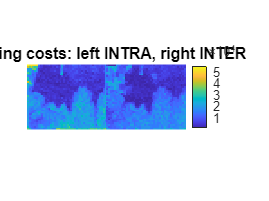

% Show the values of the coding costs
figure(2);
imagesc([mIntra, mInter]); axis image; colorbar;
title('Coding costs: left INTRA, right INTER'); axis off

% Let us compare the RD results with the Intra coding
imgBPPInter = numel(imgBitStream)/numel(img);
PSNRInter = ypsnr(img,decodedFrameBuffer.current);

img = loadInter(gopIndex,interIndex);
imgBitStreamIntra = IntraImgEncoder();
imgBPPIntra = numel(imgBitStreamIntra)/numel(img);
PSNRIntra = ypsnr(img,decodedFrameBuffer.current);
fprintf('INTER RATE: %4.3f bpp\nINTER PSNR: %4.2f dB\nINTRA RATE: %4.3f bpp\nINTRA PSNR: %4.2f dB\n',imgBPPInter,PSNRInter,imgBPPIntra,PSNRIntra);

INTER RATE: 0.927 bpp
INTER PSNR: 39.94 dB
INTRA RATE: 1.195 bpp
INTRA PSNR: 43.50 dB


## Complete encoder

Now we can test the full encoder. The provided function will seamlessly integrate with the others, namely the `gopEncoder` and the `sequenceEncoder` functions. **It is adviced to download the latest version of these functions (which is available together with this script) and to overwrite possible previous versions. **

In order to launch the encoding of a video, you have to provide all the parameters and then to call `sequenceEncoder`. In the following section we provide a code that loads a baseline configuration of the encoder: 

**How to use it: **before running a new experiment, first load all the default parameters by launching the following code (press the Load parameters button). Then, go to the section of the experiment you want to run, and launch the experiment, possibly updating the relevant parameters. 

 

% Loading the general parameters
clear all; close all;
global params img decodedFrameBuffer MVF

%------------------------------------
% Setting the configuration

params.inputVideoName = 'foreman'; % Use one of the provided .y files
params.verbose = 0;  % Setting the verboseness level is useful for debugging and testing

% Number of encoded gops and gop size
params.numberOfGops = 2; % Start with a small number of GOPS for test, then use the full sequence
params.GOPSize = 1; % GOPSsize=1 means all intra

% Quality control
params.deltaQ = 10; % difference of quality between INTRA and INTER

% RDO parameter
params.modeSelectionLambda = 100;

% ME control
params.ME.lambda = sqrt(params.modeSelectionLambda);
params.ME.radius = 7;

% Compressed file
params.compressedFileName = 'test.bin';
%------------------------------------


% Do not change these parameters: -->
params.inputVideoFile   = [params.inputVideoName '_cif.y'];
params.blockSize = 8;  %
params.nRow = 288;
params.nCol = 352;
decodedFrameBuffer.reference = zeros(params.nRow,params.nCol);
decodedFrameBuffer.current   = zeros(params.nRow,params.nCol);
MVF = zeros(params.nRow,params.nCol,2);
params.q_mtx1 =     [16 11 10 16 24 40 51 61;
    12 12 14 19 26 58 60 55;
    14 13 16 24 40 57 69 56;
    14 17 22 29 51 87 80 62;
    18 22 37 56 68 109 103 77;
    24 35 55 64 81 104 113 92;
    49 64 78 87 103 121 120 101;
    72 92 95 98 112 100 103 99];
% <-- end of parameters that should not be changed
%------------------------------------


## Experiments

Let us perform some experiment: here it is shown a list of possible experiments that you can perform by changing the parameters.

- Compare different GOP structures: Encode some images of a video sequence using different GOP structures, eg. All Intra, IPIP..., IPPIPP etc. Plot the RD curves. Notice that, if you change the GOP strutcture, you have to chose a different number of GOPs to be encoded in order to have the same number of images in all the experiments. Example: if you compare `gopSize = 2` with `gopSize=8`, in the first case you have to encoder four times as many GOPs than in the second, e.g., 8 GOPs in the first case (in total, 16 images) and two GOPs in the second (again, 16 images)

- Evaluate the number of Intra blocks in Inter coded frames. Try to understand how this value depends on the video content and on the coding quality factor. 

- Assess the effect of `params.deltaQ: `Keeping unchanged all the other parameters, assess the effect of the different quality used for Intra and Inter frames using the paramater `params.deltaQ `which tells the quality difference between the Intra and the Inter frames of the GOP. Try to understand the relationship with the video content (e.g., static video or dynamic content)

-  Assess the effect of the mode selection lambda. Evaluate the RD curves and  the mode selection ratio for different values of lambda. What happens for different sequences? 

- The `sequenceEncoder` function also returns the per-frame PSNR and rate. Draw these curves for the four sequences and try to find the relationship between content, GOP structure and the behavior of PSNR and rate. 

You can also design other experiments, in order to understand the impact of the various design choices on the final performance. 

**Question 2. Perform at least one complete experiment, report the results and comment them.  This means:**

**1. running the experiments for different sequences (note that you don't need to encode the full sequence: a number of images around 20 is typically enough);**

**2.  finding out the relevant parameters (i.e., those that have an impact on the final performance;**

**3. checking what happens by modifying the parameters / the sequence; for example, change the quality factors, the gop size, the ME parameters...**

**4. commenting the interaction among the parameters and the results. **

**Performing Experiment 3 and 4, for which no code is provided, will bring up to one *****additional***** point to your final grade (up to two points if both are implemented, executed and commented in a complete and correct fashion). **

HINT: Consider the the Matlab implementation of the video encoder is relatively slow. It is better to first test the experiment using one single GOP with a small size. Only when sure that everything works correctly, try larger GOP sizes and larger numbers of GOPs. 

%% EXPERIMENT 1
intraQualityFactorVector = [40 60 80 90];
nEncodings = numel(intraQualityFactorVector);
PSNR = zeros(nEncodings, 1);
RATE = zeros(nEncodings, 1);

% ALL INTRA
params.numberOfGops = 3;
params.GOPSize = 1;
for qualityIndex = 1:nEncodings
    params.qual = intraQualityFactorVector(qualityIndex);
    fprintf('Encoding ALL Intra with Q=%d\n', params.qual);
    [R, P] = sequenceEncoder(); %don't need input arg because param is global!
    RATE(qualityIndex) = R;
    PSNR(qualityIndex) = P;
end

Encoding ALL Intra with Q=40
Encoding ALL Intra with Q=60
Encoding ALL Intra with Q=80
Encoding ALL Intra with Q=90



% IPP gop
params.numberOfGops = 1;
params.GOPSize = 3; % let us test an IPPIPP... gop structure
PSNR2 = zeros(nEncodings, 1);
RATE2 = zeros(nEncodings, 1);
%% Main loop
for qualityIndex = 1:nEncodings
    params.qual = intraQualityFactorVector(qualityIndex);
    fprintf('Encoding IPP with Q=%d\n', params.qual);
    [R, P] = sequenceEncoder() ;
    RATE2(qualityIndex) = R;
    PSNR2(qualityIndex) = P;
end

Encoding IPP with Q=40
Encoding IPP with Q=60
Encoding IPP with Q=80
Encoding IPP with Q=90


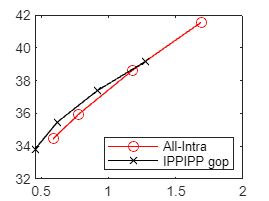


% Compare the results
figure; title(params.inputVideoName);
plot(RATE, PSNR,'ro-', RATE2, PSNR2, 'kx-') ;
legend('All-Intra', 'IPPIPP gop', 'Location','southeast');

drawnow

% Possibly load the parameters before launching this section
 

IPPIPP GOP: Shows lower PSNR for the same bitrate due to the use of inter-frame prediction, where prediction errors can accumulate across frames.

Effect of GOP Structure:

IPPIPP GOP: More efficient in terms of bitrate but sacrifices some PSNR due to prediction errors.

Quality Factor Impact: Higher quality factors generally lead to better PSNR but at the cost of higher bitrate. 

For this experiment you have to write the code. 

% Experiment 2 Evaluate the number of Intra blocks in Inter coded frames
% For this experiment you have to modify the functions in order to output
% the map of coding costs, and then use it to compute the number of blocks
% encoded in one or either mode

params.q_mtx_Intra = [16 11 10 16 24 40 51 61;
                      12 12 14 19 26 58 60 55;
                      14 13 16 24 40 57 69 56;
                      14 17 22 29 51 87 80 62;
                      18 22 37 56 68 109 103 77;
                      24 35 55 64 81 104 113 92;
                      49 64 78 87 103 121 120 101;
                      72 92 95 98 112 100 103 99];
params.q_mtx_Inter = params.q_mtx_Intra * params.deltaQ / 10; % Example for inter coding

% Load the image to be encoded (load the first frame as an example)
frameNumber = 1;
img = loadImage(params.inputVideoFile, frameNumber);

% Run the encoder with the modified functions
[bitstream, mapInter] = modifyInterImgEncoder();
[imgBitStream, mapIntra] = modifyIntraImgEncoder();

% Evaluate the number of Intra blocks in Inter coded frames
numIntraBlocks = sum(mapInter.Jintra(:) < mapInter.Jinter(:));
numInterBlocks = sum(mapInter.Jinter(:) <= mapInter.Jintra(:));

fprintf('Number of Intra blocks in Inter coded frames: %d\n', numIntraBlocks);
fprintf('Number of Inter blocks: %d\n', numInterBlocks);

`Number of Intra blocks in Inter coded frames: 0`

`Number of Inter blocks: 1584`

`Because of :`

- Motion Compensation Effectiveness: In Inter-frame coding, motion compensation is used to predict the current block from previously encoded frames. If the motion estimation finds a good match in previous frames, it's more likely to choose Inter mode over Intra mode, resulting in fewer Intra-coded blocks.

- Encoding Parameters: Parameters such as params.modeSelectionLambda and params.deltaQ can influence the encoder's decision between Intra and Inter modes. If these parameters are set to prioritize bitrate reduction or if the deltaQ is large, the encoder might favor Inter coding more often.

- Video Content Characteristics

- Block Size and GOP Structure

For this experiment you have to write the code. 

% Experiment 3: Assess the effect of params.deltaQ
% Modify the value of deltaQ and trace the RD curve. Compare different
% choices

deltaQValues = [0, 10, 20, 30];
nEncodings = numel(deltaQValues);
PSNR = zeros(nEncodings, 1);
RATE = zeros(nEncodings, 1);

% Test different deltaQ values
for deltaQIndex = 1:nEncodings
    params.deltaQ = deltaQValues(deltaQIndex);
    fprintf('Encoding with deltaQ=%d\n', params.deltaQ);
    [R, P] = sequenceEncoder();
    RATE(deltaQIndex) = R;
    PSNR(deltaQIndex) = P;
end

% Plot results
figure; title(params.inputVideoName);
plot(RATE, PSNR, 'ro-');
legend('Different deltaQ values', 'Location', 'southeast');
drawnow;


Encoding with deltaQ=0
Encoding with deltaQ=10
Encoding with deltaQ=20
Encoding with deltaQ=30


Rate Increase: As deltaQ increases, the encoder can allocate fewer bits to Inter frames, resulting in a lower bitrate (rate) for the same video sequence.

PSNR Increase: Higher deltaQ values may lead to a higher PSNR because the overall bitrate decreases while maintaining acceptable video quality. This is particularly noticeable when the video content allows for effective motion compensation and when the difference between Intra and Inter frames' quality is balanced optimally by deltaQ.

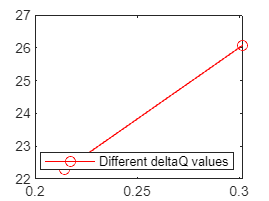

%% Experiment 4  - Effect of lambda

lambdas = [0.1  1000];
intraQualityFactorVector = [ 20 50 80 100];


RMatrix = zeros(numel(intraQualityFactorVector),numel(lambdas));
PSNRMatrix = zeros(numel(intraQualityFactorVector),numel(lambdas));

params.numberOfGops = 2; %
params.GOPSize = 5; % 

for lambdaIndex = 1:numel(lambdas)
    for qualityIndex = 1:numel(intraQualityFactorVector)
        params.qual = intraQualityFactorVector(qualityIndex);
        params.modeSelectionLambda = lambdas(lambdaIndex);
        fprintf('Encoding with Q=%d, lambda=%3.2f\n', params.qual, params.modeSelectionLambda);

        [R, P] = sequenceEncoder(); %don't need input arg because param is global!
        RMatrix(qualityIndex,lambdaIndex) = R;
        PSNRMatrix(qualityIndex,lambdaIndex) = P;
    end
end

figure; hold on; legendEntries={}; title(params.inputVideoName);
for lambdaIndex = 1:numel(lambdas)
    h=plot(RMatrix(:,lambdaIndex),PSNRMatrix(:,lambdaIndex));
    set(h,'Marker','+', 'LineWidth',2)
    legendEntries{lambdaIndex}= sprintf('\\lambda = %3.2f',lambdas(lambdaIndex ));

end
legend(legendEntries, 'Location','southeast');


Encoding with Q=20, lambda=0.10
Encoding with Q=50, lambda=0.10
Encoding with Q=80, lambda=0.10
Encoding with Q=100, lambda=0.10
Encoding with Q=20, lambda=1000.00
Encoding with Q=50, lambda=1000.00
Encoding with Q=80, lambda=1000.00
Encoding with Q=100, lambda=1000.00


% Possibly load the parameters before launching this section
 

- **Lower Lambda (0.1):** Typically results in higher PSNR at the expense of higher bitrate. It encourages more conservative mode decisions, favoring quality preservation.

- **Higher Lambda (1000):** Leads to lower bitrate but potentially lower PSNR due to aggressive mode decisions. It prioritizes compression efficiency over maintaining high visual quality.

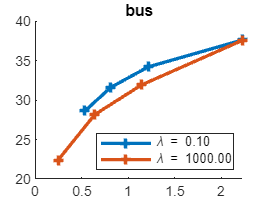

% Experiment 5
params.GOPSize=5;
params.numberOfGops = 2;

qualities = [ 30 60 90];
figure;
nImages = params.GOPSize*params.numberOfGops;

perFramePSNR = zeros(nImages,numel(qualities));
perFrameRATE = perFramePSNR; 

hold on; legendEntries={};

for qIndex = 1:numel(qualities)
    params.qual = qualities(qIndex);
    fprintf('Encoding with Q=%d\n', params.qual);
    [R, P, frameR, frameP] = sequenceEncoder();
    perFrameRATE(:,qIndex)= frameR;
    perFramePSNR(:,qIndex)= frameP;

    legendEntries{qIndex}= sprintf('QF = %d',params.qual);
end
 

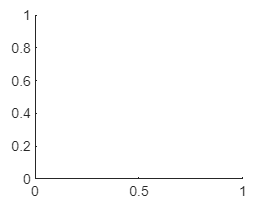

%% Draw figures for exp 5


figure; hold on;  title(params.inputVideoName);
for qIndex = 1:numel(qualities)
    plot(1:nImages,perFramePSNR(:,qIndex),'-x');
end
hold off; 
legend(legendEntries);

figure; hold on
for qIndex = 1:numel(qualities)

Encoding with Q=30
Encoding with Q=60
Encoding with Q=90


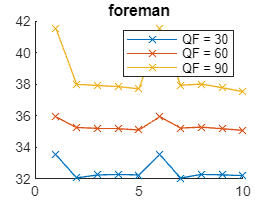

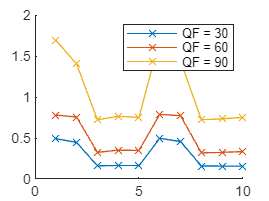

    plot(1:nImages,perFrameRATE(:,qIndex),'-x');
end
hold off; 
legend(legendEntries);
 

- **PSNR Trends:** Higher quality factors (`qualities`) result in higher PSNR across frames, indicating better visual fidelity.

- **Bitrate Trends:** Higher quality factors generally lead to higher bitrates due to less aggressive compression settings.